# Structure Response Simulation

## 1 Simulation for Response Generation

load workspace_a.mat

RS_AV = [];
RS_EQ = [];
RS_IP = [];
RS_WD = [];

### 1.1 Ambient Vibration

for i = 1:NumSeg
    % Progress
    if i/round(NumSeg/5) == fix(i/round(NumSeg/5))
        tmp_str = ['Structure Response subjected to Ambient Vibration ' num2str(i) '/' num2str(NumSeg)];
        disp(tmp_str)
    end
    
    % Simulation
    ExcitationInput = TS_AV{i};
    AV_Sim = sim('MDOF_AV.slx');
    TMPRS_AV = AV_Sim.ResponseOutput.signals.values;

    % Integration
    for j = 1:nDOF
        RS_AV(i,j,:) = squeeze(TMPRS_AV(2:end,j));
    end
end

Structure Response subjected to Ambient Vibration 1/5
Structure Response subjected to Ambient Vibration 2/5
Structure Response subjected to Ambient Vibration 3/5
Structure Response subjected to Ambient Vibration 4/5
Structure Response subjected to Ambient Vibration 5/5


disp('size of response matrix')

size of response matrix


size(RS_AV)

ans =            5           5       12000


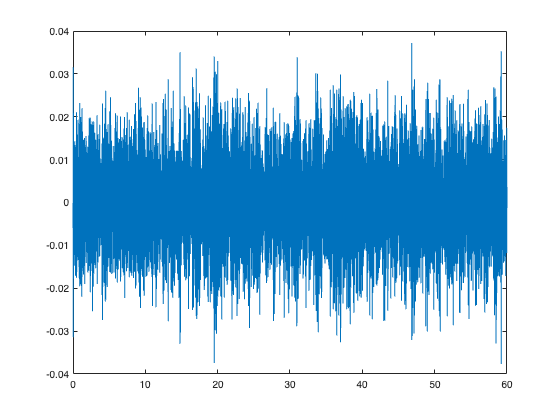

figure
plot(TimeSeries,squeeze(RS_AV(1,1,:)))


fn_tmp = 'RS_AV.mat';
save(fn_tmp,'RS_AV')

### 1.2 Earthquake

for i = 1:NumSeg
    % Progress
    if i/round(NumSeg/5) == fix(i/round(NumSeg/5))
        tmp_str = ['Structure Response Subjected to Earthquake ' num2str(i) '/' num2str(NumSeg)];
        disp(tmp_str)
    end
    
    % Simulation
    ExcitationInput = TS_EQ{i};
    EQ_Sim = sim('MDOF_EQ.slx');
    TMPRS_EQ = EQ_Sim.ResponseOutput.signals.values;

    % Integration
    for j = 1:nDOF
        RS_EQ(i,j,:) = squeeze(TMPRS_EQ(2:end,j));
    end
end

Structure Response Subjected to Earthquake 1/5
Structure Response Subjected to Earthquake 2/5
Structure Response Subjected to Earthquake 3/5
Structure Response Subjected to Earthquake 4/5
Structure Response Subjected to Earthquake 5/5


disp('size of response matrix')

size of response matrix


size(RS_EQ)

ans =            5           5       12000


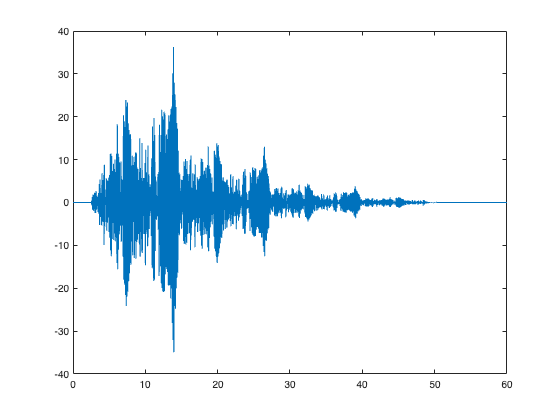

figure
plot(TimeSeries,squeeze(RS_EQ(1,1,:)))


fn_tmp = 'RS_EQ.mat';
save(fn_tmp,'RS_EQ')

### 1.3 Impact

for i = 1:NumSeg
    % Progress
    if i/round(NumSeg/5) == fix(i/round(NumSeg/5))
        tmp_str = ['Structure Response Subjected to Impact ' num2str(i) '/' num2str(NumSeg)];
        disp(tmp_str)
    end
    
    % Simulation
    ExcitationInput = TS_IP{i};
    IP_Sim = sim('MDOF_IP.slx');
    TMPRS_IP = IP_Sim.ResponseOutput.signals.values;

    % Integration
    for j = 1:nDOF
        RS_IP(i,j,:) = squeeze(TMPRS_IP(2:end,j));
    end
end

Structure Response Subjected to Impact 1/5
Structure Response Subjected to Impact 2/5
Structure Response Subjected to Impact 3/5
Structure Response Subjected to Impact 4/5
Structure Response Subjected to Impact 5/5


disp('size of response matrix')

size of response matrix


size(RS_IP)

ans =            5           5       12000


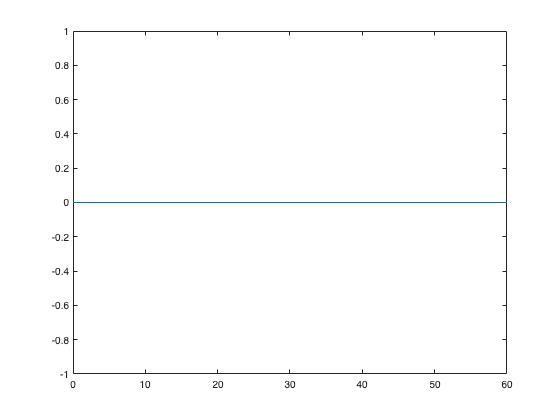

figure
plot(TimeSeries,squeeze(RS_IP(1,1,:)))

fn_tmp = 'RS_IP.mat';
save(fn_tmp,'RS_IP')

### 1.4 Wind

for i = 1:NumSeg
    % Progress
    if i/round(NumSeg/5) == fix(i/round(NumSeg/5))
        tmp_str = ['Structure Response Subjected to Strong Wind ' num2str(i) '/' num2str(NumSeg)];
        disp(tmp_str)
    end
    
    % Simulation
    ExcitationInput = TS_WD{i};
    WD_Sim = sim('MDOF_WD.slx');
    TMPRS_WD = WD_Sim.ResponseOutput.signals.values;

    % Integration
    for j = 1:nDOF
        RS_WD(i,j,:) = squeeze(TMPRS_WD(2:end,j));
    end
end

Structure Response Subjected to Strong Wind 1/5
Structure Response Subjected to Strong Wind 2/5
Structure Response Subjected to Strong Wind 3/5
Structure Response Subjected to Strong Wind 4/5
Structure Response Subjected to Strong Wind 5/5


disp('size of response matrix')

size of response matrix


size(RS_WD)

ans =            5           5       12000


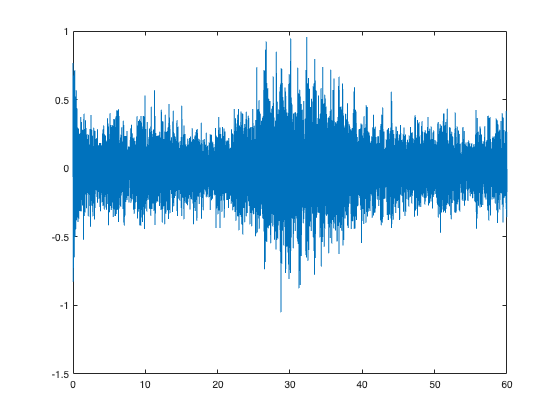

figure
plot(TimeSeries,squeeze(RS_WD(1,1,:)))


fn_tmp = 'RS_WD.mat';
save(fn_tmp,'RS_WD')  

## 2 Data Integration

% Integration
Data_Raw = [];
TMP = [];
for i = 1:NumSeg
    for j = 1:nDOF
        for m = 1:4
            if m == 1
                TMP = RS_AV;
            elseif m == 2
                TMP = RS_EQ;
            elseif m == 3
                TMP = RS_IP;
            else
                TMP = RS_WD;
            end
            Data_Raw(i,j,m,:) = squeeze(TMP(i,j,:));
        end
    end
end
fn_tmp = 'Data_Raw.mat';
save(fn_tmp,'Data_Raw')  

% RAW_RS for saving
RAW_RS = [];
for m = 1:4
    for i = 1:NumSeg
        for j = 1:nDOF
            tmp_ind = (m-1)*NumSeg*nDOF + (i-1)*nDOF + j;
            RAW_RS(:,tmp_ind) = squeeze(Data_Raw(i,j,m,:));
        end
    end
end

fn_tmp = 'RAW_RS.mat';
save(fn_tmp,'RAW_RS')  

% fn_tmp = 'RAW_RS.csv';
% save(fn_tmp,'RAW_RS')

save workspace_b.mat